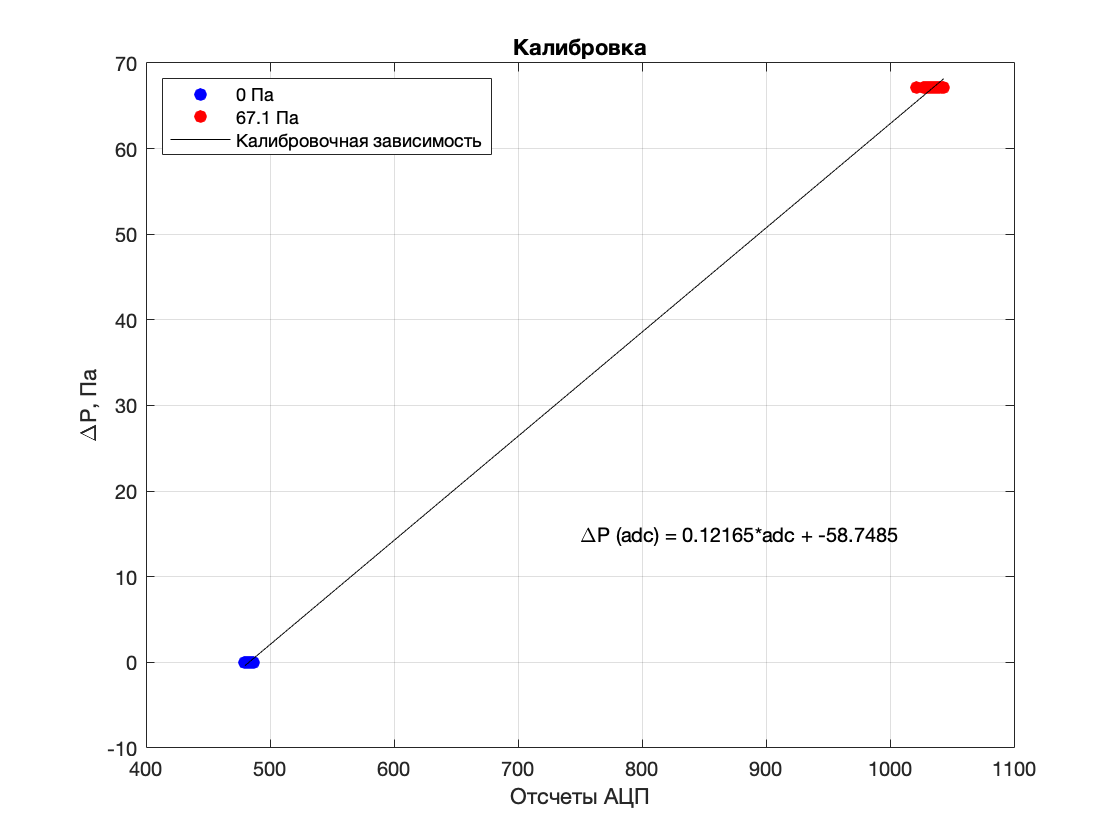

calibzero0 = load('calibzero.dat');
calib0 = load('calib.dat');

calibzero = (calibzero0(:,2))';
calib = (calib0(:,2))';
no_null = ones(size(calib)).*67.1;
null = zeros(size(calibzero));
temp_1 = [calibzero calib];
temp_2 = [null no_null];
t = polyfit(temp_1, temp_2, 1);

f = figure;
figure(f);
plot(calibzero, null, 'bo', 'MarkerFaceColor','b');
hold on;
plot(calib, no_null, 'ro', 'MarkerFaceColor','r');
grid on;
x1 = [min(calibzero) max(calib)];
y1 = [polyval(t, x1(1)) polyval(t, x1(2))];
plot(x1, y1, 'Color', 'k');

title('Калибровка');
xlabel('Отсчеты АЦП');
ylabel('\DeltaP, Па');
str = ['\DeltaP (adc) = ' num2str(t(1)) '*adc + ' num2str(t(2))];
text(750, 15, str);
legend('0 Па', '67.1 Па', 'Калибровочная зависимость', 'Location','northwest');
saveas(f, 'calibration.png');

clear all;